Final Project

Tol = 1e-4;
N = 1000;
n = 20;
h = (pi)/(n+1);
A = diag(-2*ones(n,1),0) + diag(1*ones(n-1,1),1) + diag(1*ones(n-1,1),-1);
L = tril(A);
U = triu(A);
D = diag(diag(A));
tmp = linspace(0,pi,n+2);
x = tmp(2:end - 1);
f = h^2 *transpose(sin(x));
x0 = zeros(1,n);
T_j = - inv(D)*(L+U)

T_j =    -2.0000    0.5000         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    0.5000   -2.0000    0.5000         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0    0.5000   -2.0000    0.5000         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0    0.5000   -2.0000    0.5000         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0    0.5000   -2.0000    0.5000         0         0         0         0         0         0         0         0         0         0         0         0         0

x1 = ones(n,1);

Jacobi Method

Jacobi(A,f,x0,Tol,N);

Max number of iterations exceeded


Gauss Siedel

Gauss(A,f,x0,Tol,N);

k = 294

SOR

SOR(A,f,x0,Tol,N,1.5);

k = 111

Power Method

Power(T_j,x1,Tol,N)

mu =    -0.0833   -0.0833    0.0017         0   -0.0833   -0.0833   -0.0833   -0.0833   -0.0833   -0.0833   -0.0833   -0.0833   -0.0833   -0.0833   -0.0833   -0.0833   -0.0833   -0.0833   -0.0833   -0.0833


x =     0.0417
    0.0033
   -0.0000
         0
         0
         0
         0
         0
         0
         0


k = 4

ans =     0.0417
    0.0033
   -0.0000
         0
         0
         0
         0
         0
         0
         0


Plot

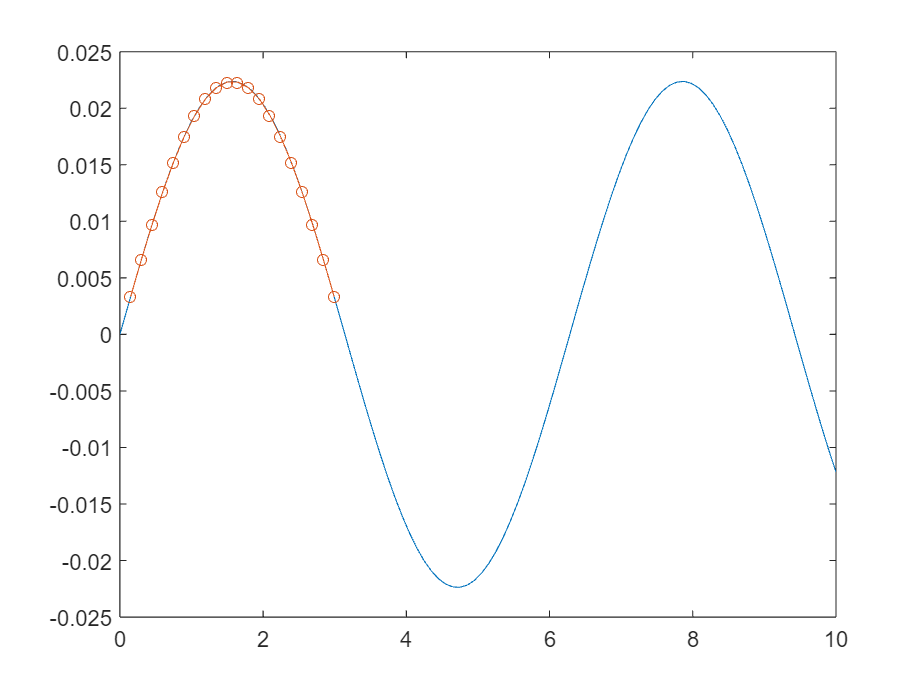

z = linspace(0,10,100);
figure
plot(z,h^2*sin(z)); hold on
plot(u, h^2*sin(u), 'Marker','o', 'MarkerSize', 5)

SOR Function

function [y] = SOR(A , b, x0, Tol, N, w)
 k = 0;
 n = length(A);
 x = zeros(n,1);
 XO = x;
 while k <= N
 for i = 1:n
 x(i) = (1-w)*XO(i) + ( (w / A(i,i)) * (b(i)- A(i, 1:i-1 )*x(1:i-1) - A(i,i+1:n)*XO(i+1:n)) );
 end
 if norm(x - XO) < Tol
 k
 return;
 end
 k = k + 1;
 for i = 1:n
 XO(i) = x(i);
 end
 end
 if k > N
 disp('Max number of iterations exceeded');
 end
end


Jacobi Function

function [x] = Jacobi(A , b ,x0 , Tol, N)
 k = 0;
 n = length(A);
 x = zeros(n,1);
 XO = x0;
while k <= N
    for i = 1:n
        x(i) = b(i) - sum((A(i,[1:i-1,i+1:n]).*XO([1:i-1,i+1:n])))/A(i,i);
    end
    if norm(x - XO) < Tol
        k
        break;
    end
    k = k+1;
    for i = 1:n
        XO(i) = x(i);
    end
    if k == N +1
        disp("Max number of iterations exceeded")
    end
end
end



Gauss Siedel Method

function [y] = Gauss(A,b,x0,Tol,N)
n= length(A);
XO = zeros(1,n);
x = zeros(1,n);
k = 0;

while k <= N
    for i = 1:n
        x(i) = (b(i) - sum((A(i,1:i-1).*x(1:i-1)))-sum(A(i,i+1:n).*XO(i+1:n)))/A(i,i);
    end
    if norm(x - XO) < Tol
        k
        break;
    end
    k = k+1;
    for i = 1:n
        XO(i) = x(i);
    end
    if k == N +1
        disp("Max number of iterations exceeded")
    end
end
end

Power Method

function [x] = Power(A,x,Tol,N)
k = 0;
[~,p] = max(abs(x));

x  = x/x(p);
while k <= N
    y = A.*x;
    mu = y(p);
    [~,p] = max(abs(y));
    if y(p) == 0
        error('Eigenvector x has eigenvalue 0')
    end
    ERR = norm(x - y/y(p));
    x = y/y(p);
    if ERR < Tol
        mu
        x
        k
        return;
    end
    k = k+1;

end
error('Maximum iterations exceeded')
end
